x = (0:0.5:5.0)'

x =          0
    0.5000
    1.0000
    1.5000
    2.0000
    2.5000
    3.0000
    3.5000
    4.0000
    4.5000


y = [2.89 3.37 3.98 4.52 5.06 5.61 6.20 6.76 7.30 7.87 8.40]'

y =     2.8900
    3.3700
    3.9800
    4.5200
    5.0600
    5.6100
    6.2000
    6.7600
    7.3000
    7.8700



x = x .* 10^-3 .* 9.8

x =          0
    0.0049
    0.0098
    0.0147
    0.0196
    0.0245
    0.0294
    0.0343
    0.0392
    0.0441


y = y .* 10^-2

y =     0.0289
    0.0337
    0.0398
    0.0452
    0.0506
    0.0561
    0.0620
    0.0676
    0.0730
    0.0787


 p = fittype('poly1')

p =      Linear model Poly1:
     p(p1,p2,x) = p1*x + p2

 f = fit(x, y, p)

f =      Linear model Poly1:
     f(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =       1.134  (1.124, 1.144)
       p2 =     0.02854  (0.02825, 0.02883)

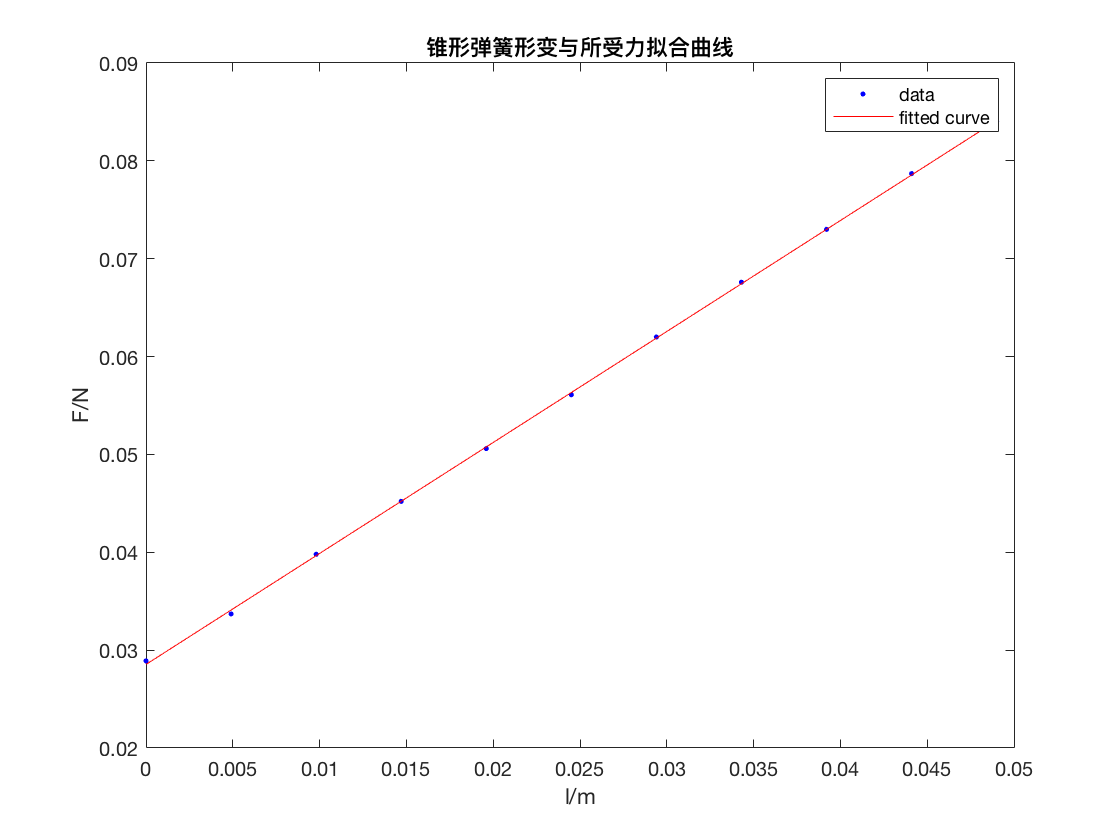

ans = 1.1341

ans = 0.0285

Error using cfit/subsref (line 18)
The name 'fitoptions' is not a coefficient or a problem parameter.  You can only use dot notation to access the coefficients and problem parameters of a cfit or sfit, e.g., 'f.p1'.

For the current fit, you can access these properties: p1, p2

You can get coefficient names and values either by name, e.g., p1 = f.p1, or by using the coeffnames or coeffvalues functions, e.g., names = coeffnames(f).

To use methods, use functional notation instead, e.g., plot(f).

figure
plot(f, x, y)
xlabel('l/m')
ylabel('F/N')
title('锥形弹簧形变与所受力拟合曲线')